# Delsys FileReaderAPI - Matlab

This document outlines how to directly read SHPF files within a MATLAB environment using Delsys' FileReaderAPI

You can run this example or export it to MATLAB script (.m)

## How to export this example as a matlab script (if desired)

Click file>save as and choose .m file.

## Matlab Example

### Setup the FileReader

First create the *FileReader* object by passing it in the path to the dependencies is this example directory. 

close all; clear;
pathToDll = fullfile(pwd + "\" + "dependencies" + "\");
fileReader = FileReader(pathToDll);

### Choosing a file to read

You can read a file by calling the .Read() method and passing the full path to the shpf file.

Calling the method *ParsedFile()* will return a file object that contains all the data from that file.

filePath = pwd + "\" + "Forearm_Pronation_Supination_1.delsys";

fileReader.Read(filePath);

fileReader.ParsedFile();

fileType = fileReader.FileType();

### Navigating The File

You can loop through trials, the sensors within the trial, and the channels iwthin the sensor, by using indexing

gap = "—— ";
for i = 1:fileReader.TrialCount()
    trial = fileReader.Trial(i);
    disp(strcat("Trial: ", trial.Name()));

    for j = 1:trial.ComponentCount()
        component = trial.Component(j);
        disp(strcat(gap, "Component: ", component.Name()));

        for k = 1:component.ChannelCount()
            channel = component.Channel(k);
            disp(strcat(gap, gap, "Channel: ", channel.Name()));
        end
    end
end

Trial: Forearm_Pronation_Supination_1


—— Component: Avanti Sensor


—— —— Channel: R Pronator Teres
—— —— Channel: ACC X
—— —— Channel: ACC Y
—— —— Channel: ACC Z
—— —— Channel: GYRO X
—— —— Channel: GYRO Y
—— —— Channel: GYRO Z


### Retrieving Data

After the file is parsed all of the individual sensor component objects are stored in an array. The file provided with this example only has one sensor's data, therefore we will reference index 1 to retrieve the first component in that array. If more sensors were used during a collection, you may loop through the sensor objects by using the total number of sensors in the file. To see all of the metadata and methods associated with each component object see Component.m 

file = fileReader.Trial(1);
component1 = file.Component(1);
file.Name()

ans = "Forearm_Pronation_Supination_1"

component1.Name()

ans = "Avanti Sensor"

### `Get Data from a single Channel `

Each component object contains a list of channel objects. This example will pull the first channel from component1 object. Each channel object has a variety of metadata along with all of the channel data. To see all of the metadata and methods associated with each channel object see Channel.m 

%Channel functions
channel1 = component1.Channel(1);
xydata = file.GetChannelXyData(channel1.Guid);
channelydata = double(xydata.yData);
channelxdata = double(xydata.xData);
disp("Channel Name: " + channel1.Name())

Channel Name: R Pronator Teres


### `Get All Data from a component`

You can get all channel data (for a single sensor component) and other metadata with these method calls.

%data = component1.GetAllData(); loads all component data into memory
names = component1.GetAllChannelNames();
sampleRates = component1.GetAllSampleRates();
units = component1.GetAllUnits();

for i = 1:length(names)
    disp("--Channel: " + names(i) + " Sample Rate: " + sampleRates(i) + " Unit: " + units(i))
end

--Channel: R Pronator Teres Sample Rate: 1259.2593 Unit: MILLIVOLTS
--Channel: ACC X Sample Rate: 148.1481 Unit: G
--Channel: ACC Y Sample Rate: 148.1481 Unit: G
--Channel: ACC Z Sample Rate: 148.1481 Unit: G
--Channel: GYRO X Sample Rate: 148.1481 Unit: DEG_S
--Channel: GYRO Y Sample Rate: 148.1481 Unit: DEG_S
--Channel: GYRO Z Sample Rate: 148.1481 Unit: DEG_S


`Plotting single channel of data`

`Here the EMG data is plotted on its own figure`

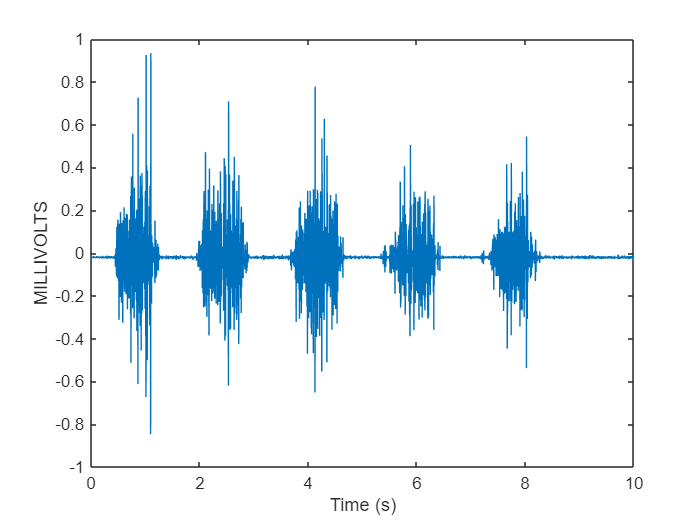

%Outputs
figure
plot(channelxdata,channelydata)
xlabel('Time (s)')
ylabel(channel1.Units())

`Plotting all data from sensor component`

`Here all of the data is plotted based on the channel type (EMG, ACC, GRYO)`

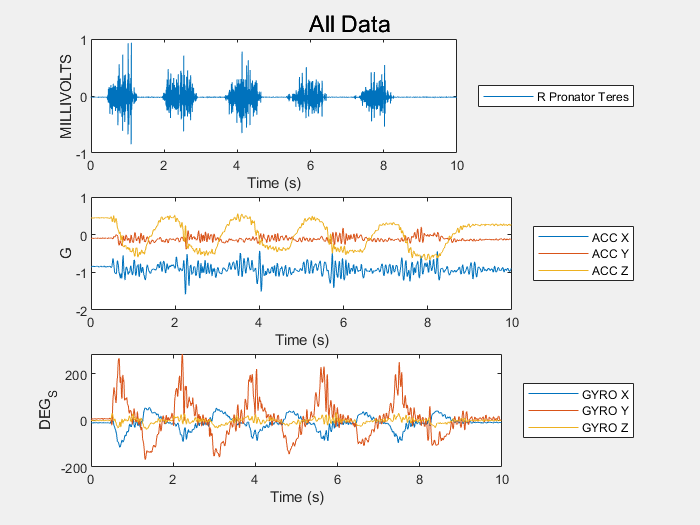

channel_types = strings([1,component1.ChannelCount()]);

for i = 1:component1.ChannelCount()
    channel_types(i) = component1.Channel(i).ChannelType();
end

%Get array of all the unique channel types (ie. EMG, ACC, GYRO)
unique_channel_types = unique(channel_types,'stable');

figure
sgtitle("All Data")

%Loop all unique channel types
for i = 1:length(unique_channel_types)
    
    %Loop all channel data - if channel type matches, add the channel data to that plot
    for k = 1:component1.ChannelCount()
        if component1.Channel(k).ChannelType() == unique_channel_types(i)
            %Get channel data
            xydata = file.GetChannelXyData(component1.Channel(k).Guid);
            channelydata = double(xydata.yData);
            channelxdata = double(xydata.xData);
            %Add data to plot
            subplot(length(unique_channel_types),1,i);
            plot(channelxdata, channelydata,'DisplayName', component1.Channel(k).Name());
            hold on;
            
            % Set axes titles and legend
            xlabel("Time (s)")
            ylabel(component1.Channel(k).Units())
            legend('location', 'eastoutside')
        end
    end
end
uicontrol('Visible','off')

`Close the open file`

`Close the file stream`

fileReader.Close()